Proyecto 4 - Reconstrucción de Bases De Datos. 

Reconstrucción de Matrices 'Gappy' usando SVD truncada. 

En este script, voy a recoger todos los resultados obtenidos y representar graficamente algunos ejemplos. Primero generamos , a partir de unas matrices construidas, unas matrices de datos incompletas ('gappy') o con huecos. Y finalmente aplicamos la reconstrucción iterativa con el algortimo que usa SVD truncada. 

1. Generación de las bases de datos A1, A2, A3 y las tres bases de datos 'gappy' A1_gappy, A2_gappy, A3_gappy

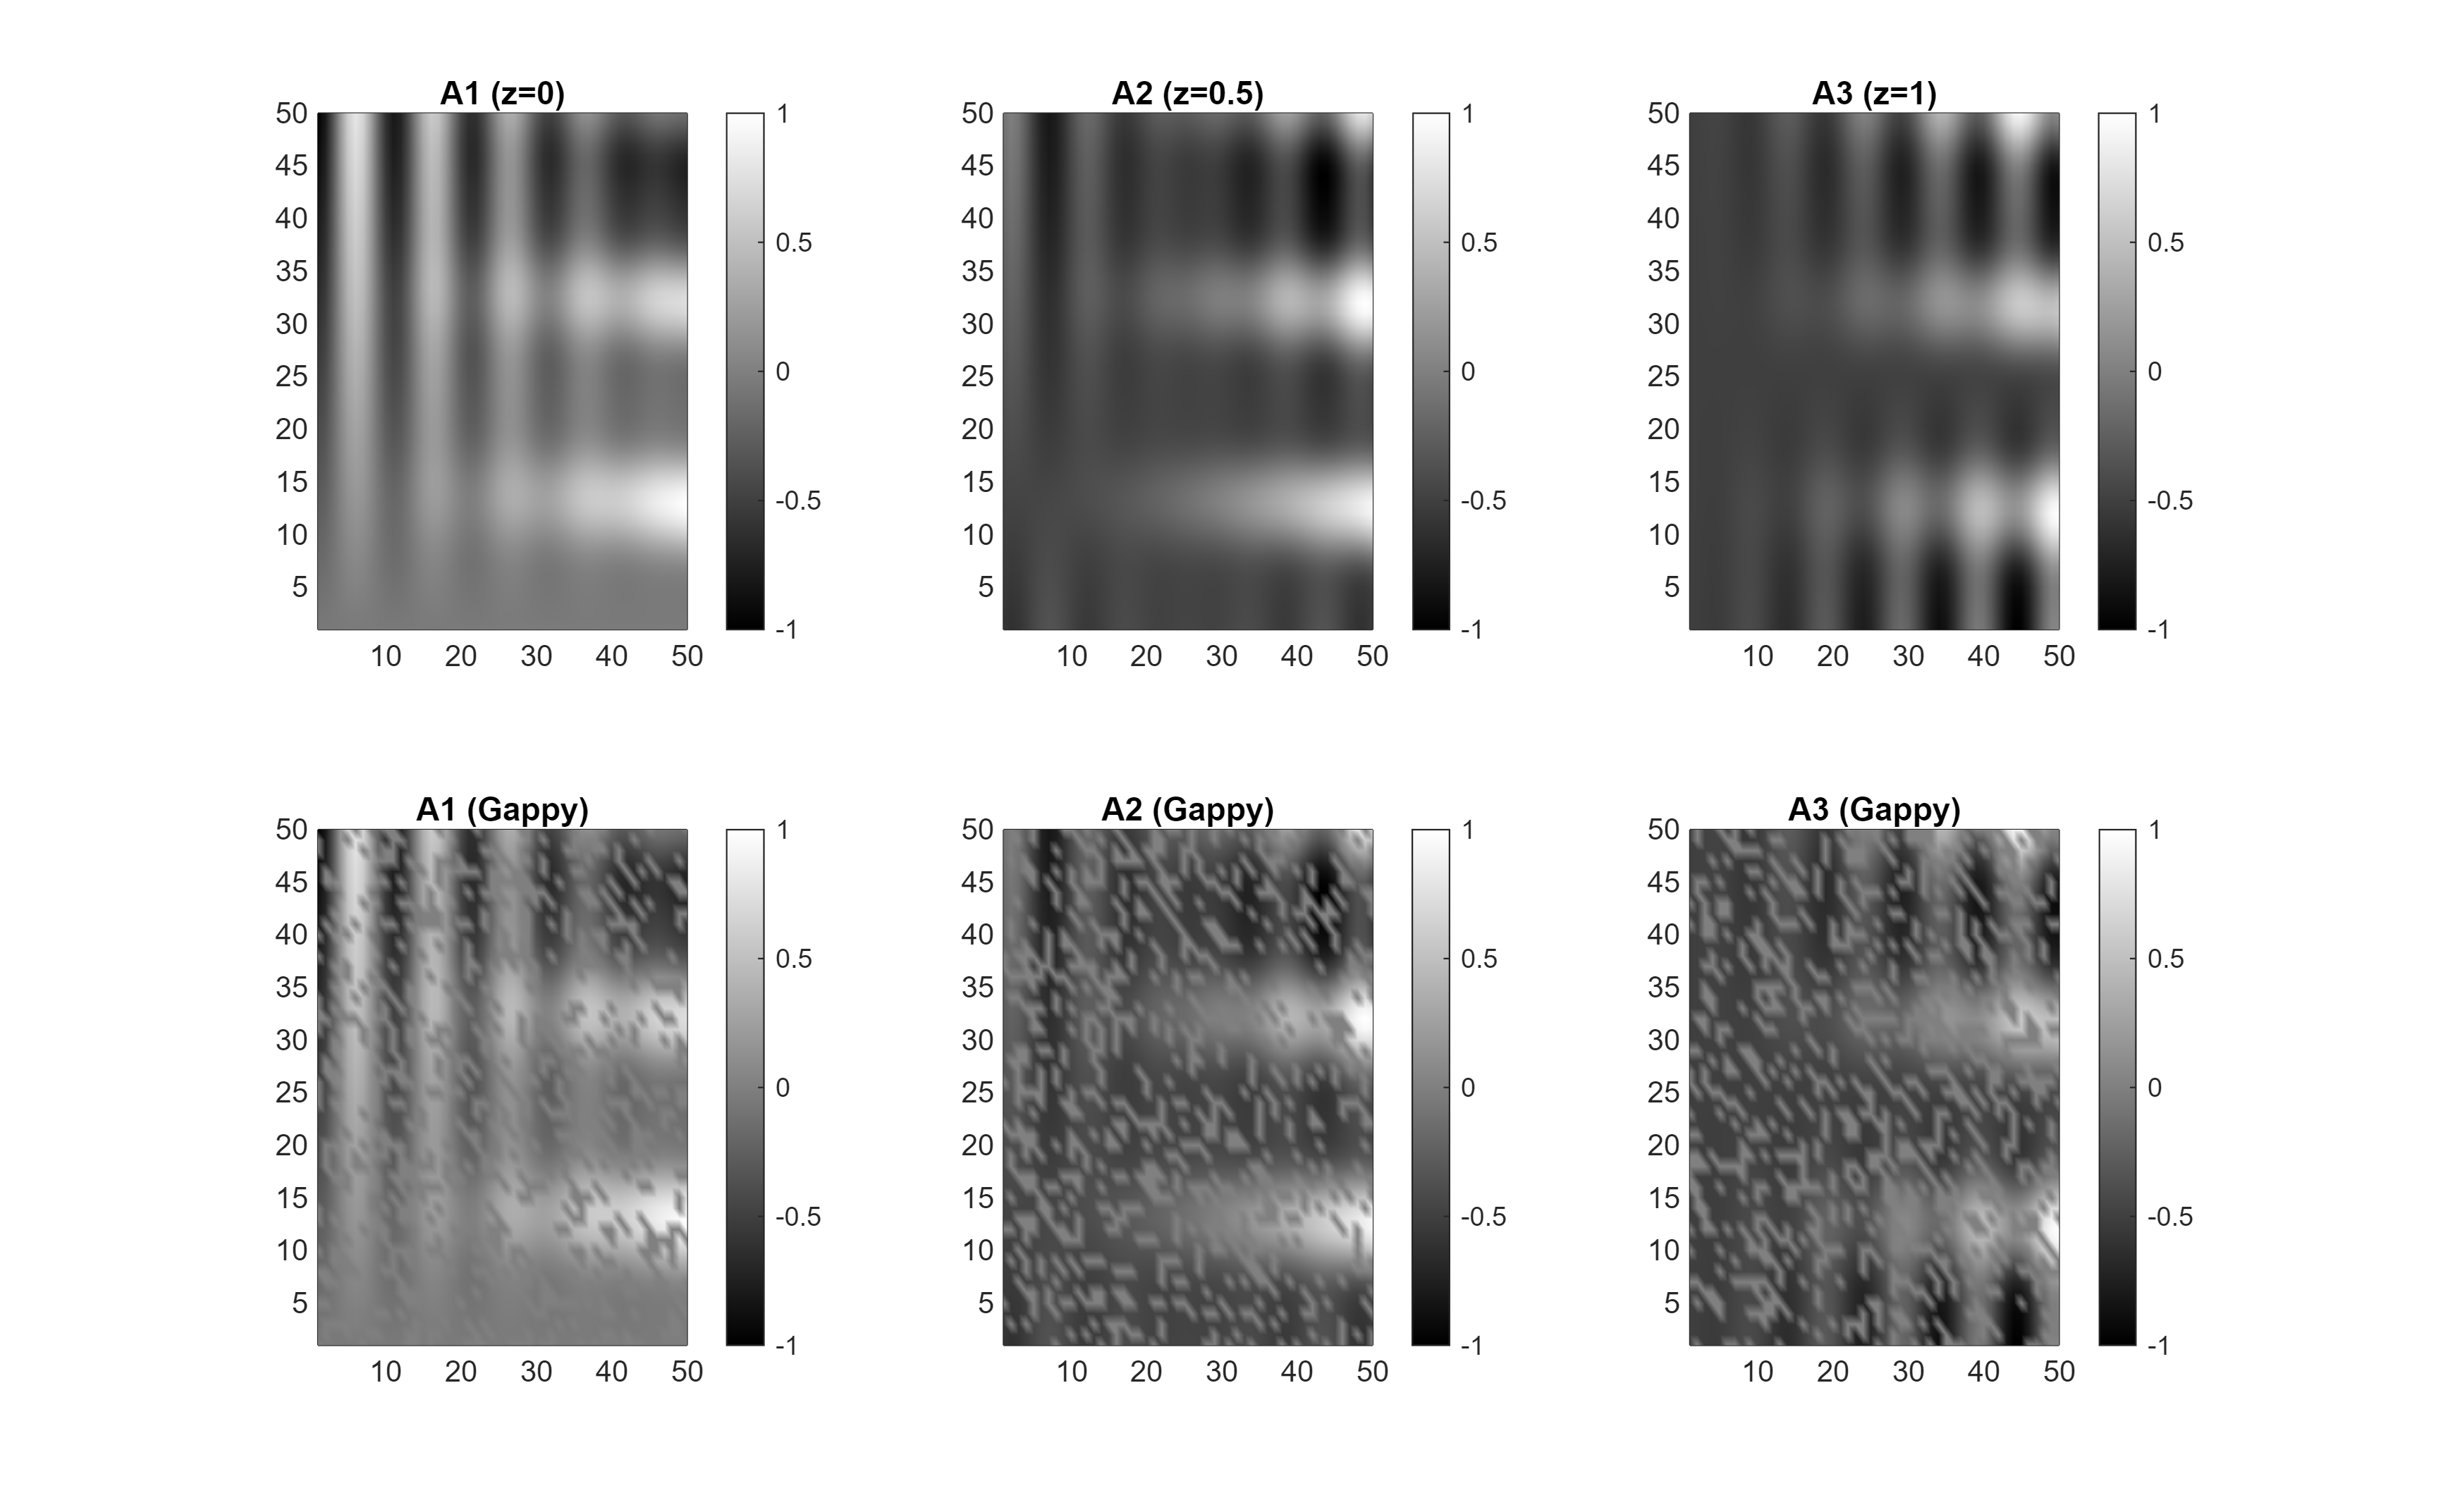

%Parámetros
N = 50; %Tamaño de la matriz
Delta_x = 1 / (N-1);
[x, y] = meshgrid( (0:N-1)* Delta_x, (0:N-1) * Delta_x);
z_val = [0, 0.5, 1]; %Valores de z*

%Función f. 0<= x,y,z<=1
f = @(x, y, z) x.^2 .*(sin(5*pi*y + 3*log(x.^3 + y.^2 + z +pi^2)) -1).^2 -...
    4*x.^2 .*y.^3.*(1-z)^(3/2) + (x + z - 1) .* (2*y - z) .* cos(30*(x + z))...
    .* log(6 + x.^2.*y.^2 + z.^3);

%Transformación T : F(x,y,z) = T(f(x,y,z)) = 2.*(f(x,y,z) - f_min) ./
%(f_ma x- f_min) - 1

%Generación de las matrices
z1 = z_val(1); z2 = z_val(2); z3 = z_val(3);
A1 = f(x, y, z1); A2 = f(x, y, z2); A3 = f(x, y, z3);

%Construcción de las bases de datos
f_min1 = min(A1(:)); f_max1 = max(A1(:));
f_min2 = min(A2(:)); f_max2 = max(A2(:));
f_min3 = min(A3(:)); f_max3 = max(A3(:));

A1 = 2 * (A1 - f_min1) / (f_max1 - f_min1) - 1;
A2 = 2 * (A2 - f_min2) / (f_max2 - f_min2) - 1;
A3 = 2 * (A3 - f_min3) / (f_max3 - f_min3) - 1;

%Generación bases de datos 'gappy' A1, A2, A3
w = 0.3;  %Porcentaje de elementos eliminados
%Eliminar aleatoriamente el procentaje de elementos de la base de datos
elems1 = rand(N, N) > w;
elems2 = rand(N, N) > w;
elems3 = rand(N, N) > w;
A1_gappy = A1 .* elems1;
A2_gappy = A2 .* elems2;
A3_gappy = A3 .* elems3;

%Resultados 
figure;
set(gcf, 'Position', [100, 100, 1050, 650]);

    %Bases de datos 
subplot(2,3,1); pcolor(A1); shading interp; colormap('gray'); colorbar; title('A1 (z=0)');
subplot(2,3,2); pcolor(A2); shading interp; colormap('gray'); colorbar; title('A2 (z=0.5)');
subplot(2,3,3); pcolor(A3); shading interp; colormap('gray'); colorbar; title('A3 (z=1)');
    %Bases de datos 'gappy'
subplot(2,3,4); pcolor(A1_gappy); shading interp; colormap('gray'); colorbar; title('A1 (Gappy)');
subplot(2,3,5); pcolor(A2_gappy); shading interp; colormap('gray'); colorbar; title('A2 (Gappy)');
subplot(2,3,6); pcolor(A3_gappy); shading interp; colormap('gray'); colorbar; title('A3 (Gappy)');

2. Algoritmo iterativo para la reconstrucción de una matriz 'gappy' aplicando SVD truncada (con un número fijo de modos m)

%Reconstrucción SVD truncada, con un número fijo m de modos

function A_rec = truncated_svd (A_gappy, m, max_iter, tol)
    %Algoritmo iterativo para reconstrucción de matrices 'gappy' usando SVD

    %Parámetros:
    %   -A_gappy: Matriz con un cierto porcentaje de elementos vacíos
    %   -m: Número de modos fijos   
    %   -tol: tolerancia para la convergencia
    %   -max_iter: número maximo de iteraciones

    [~,N] = size(A_gappy);


    %Elementos eliminados de la matriz, valores 'gappy'
    elems = isnan(A_gappy);

    %Reconstrucción inicial A_0
    A_0 = A_gappy;

    % Opción 1: Usar la media de los valores conocidos (actual)
    valor_medio = mean(A_gappy(~elems), 'all');
    A_0(elems) = valor_medio; %Rellenamos los huecos con la media para que no sean NaN
    

    A_rec = A_0;
    iter = 0;
    RMSE_prev = inf; 

    while iter < max_iter
        iter = iter + 1;

        %Aplicamos SVD a la matriz inicial
        [U, S, V] = svd(A_rec);

    
        % Extraer los valores singulares y ordenarlos
        valores_singulares = diag(S);
        [m_valores, idx] = sort(valores_singulares, 'descend');
        
        % Tomar los m valores singulares más grandes
        if m < length(m_valores)
            m_valores(m+1:end) = 0;
        end
        
        % Construir nueva matriz S con solo los m valores singulares más grandes
        S_trunc = zeros(size(S));
        for i = 1:min(m, length(m_valores))
            S_trunc(idx(i), idx(i)) = m_valores(i);
        end

        %Reconstruccion de los m modos principales
        A_s = U* S_trunc* V';

        %Restaurar los puntos 'non-gappy'
        A_s(elems) = A_gappy(elems);

         %Calculo error
        RMSE = (1/N) *norm(A_rec - A_s, 'fro'); %Norma frobenius, ||.||_2
        
        %Criterio de parada 
        if RMSE < tol
            break;
        end
        RMSE_prev = RMSE; 

        %Matriz reconstruida
        A_rec = A_s;
    end
end

Cambiamos la reconstrucción inicia tomando valores aleatorios en vez de la media de los valores y definimos una nueva función para poder luego ver las diferencias. 

%Reconstrucción SVD truncada, con un número fijo m de modos
%Reconstrucción inicial con valores aleatorios

function A_rec = truncated_svd2 (A_gappy, m, max_iter, tol)
    %Algoritmo iterativo para reconstrucción de matrices 'gappy' usando SVD

    %Parámetros:
    %   -A_gappy: Matriz con un cierto porcentaje de elementos vacíos
    %   -m: Número de modos fijos   
    %   -tol: tolerancia para la convergencia
    %   -max_iter: número maximo de iteraciones

    [~,N] = size(A_gappy);


    %Elementos eliminados de la matriz, valores 'gappy'
    elems = isnan(A_gappy);

    %Reconstrucción inicial A_0
    A_0 = A_gappy;

    
    % Opción 2: Usar valores aleatorios en los huecos
    A_0(elems) = rand(size(A_gappy(elems))) * 2 - 1; % Números entre -1 y 1

    A_rec = A_0;
    iter = 0;
    RMSE_prev = inf; 

    while iter < max_iter
        iter = iter + 1;

        %Aplicamos SVD a la matriz inicial
        [U, S, V] = svd(A_rec);

    
        % Extraer los valores singulares y ordenarlos
        valores_singulares = diag(S);
        [m_valores, idx] = sort(valores_singulares, 'descend');
        
        % Tomar los m valores singulares más grandes
        if m < length(m_valores)
            m_valores(m+1:end) = 0;
        end
        
        % Construir nueva matriz S con solo los m valores singulares más grandes
        S_trunc = zeros(size(S));
        for i = 1:min(m, length(m_valores))
            S_trunc(idx(i), idx(i)) = m_valores(i);
        end

        %Reconstruccion de los m modos principales
        A_s = U* S_trunc* V';

        %Restaurar los puntos 'non-gappy'
        A_s(elems) = A_gappy(elems);

         %Calculo error
        RMSE = (1/N) *norm(A_rec - A_s, 'fro'); %Norma frobenius, ||.||_2
        
        %Criterio de parada 
        if RMSE < tol
            break;
        end
        RMSE_prev = RMSE; 

        %Matriz reconstruida
        A_rec = A_s;
    end
end

Tomamos la matriz A1 definida anteriormente y vemos la diferencia gráfica de la reconstrucción

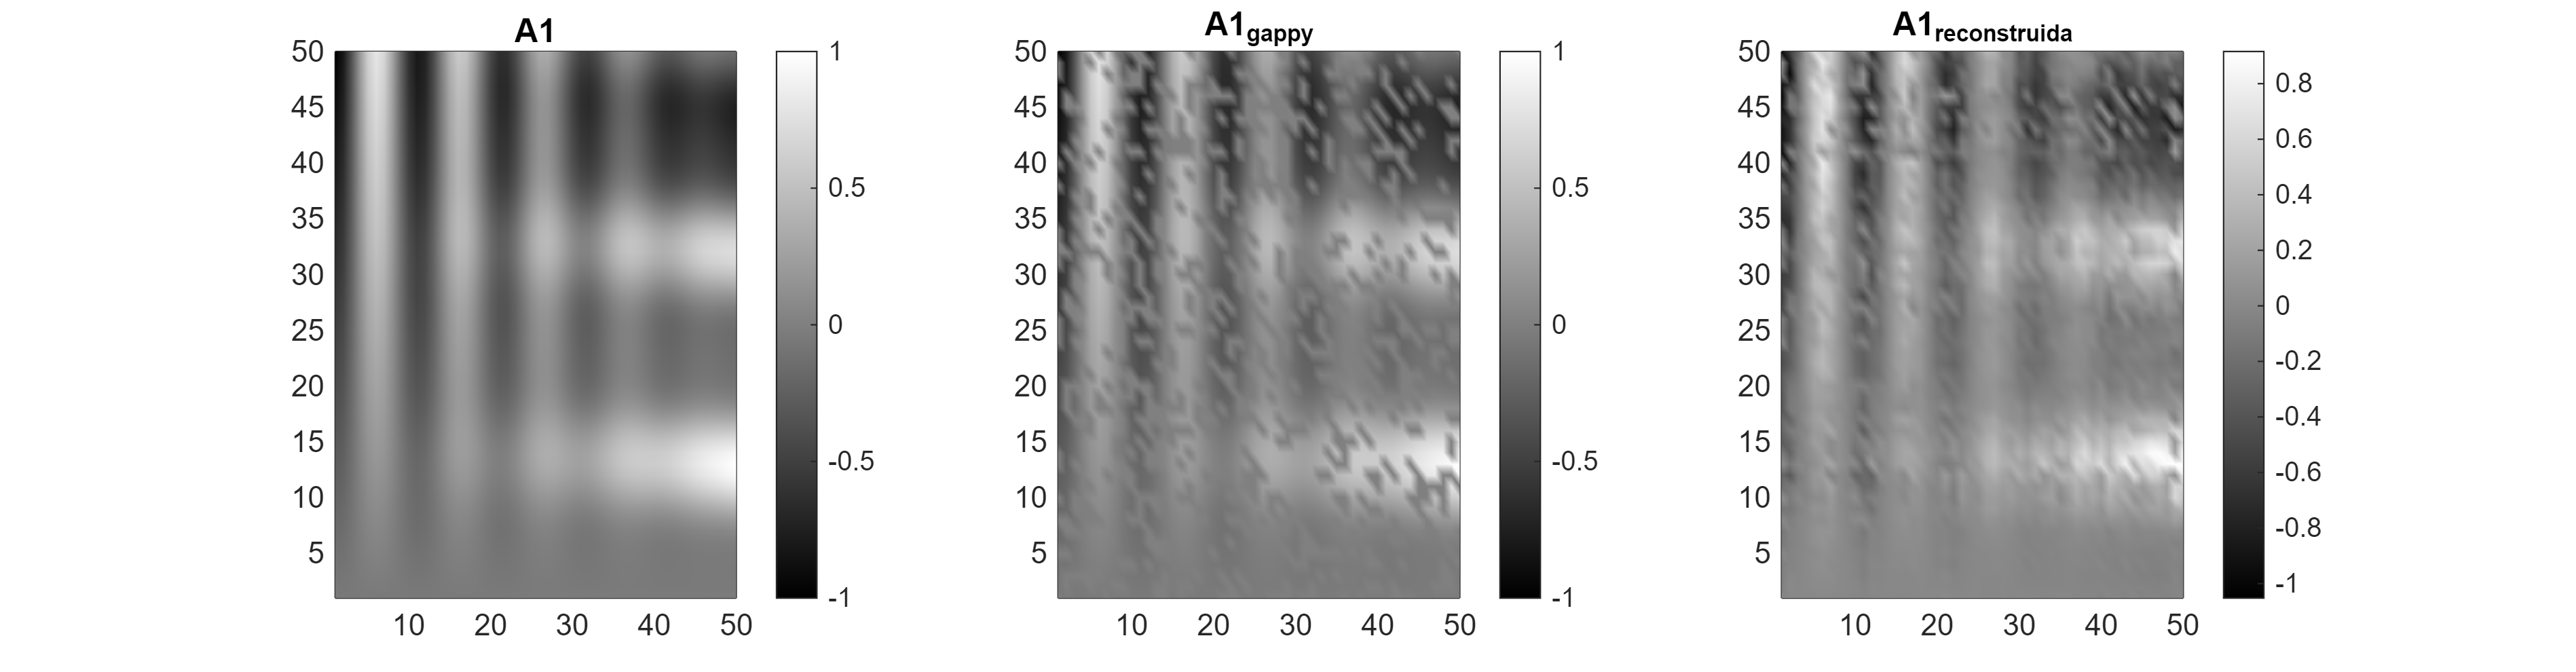

%Comparación gráfica de las 3 matrices
m = 7;
max_iter = 1000;
tol = 1e-6;
A_rec = truncated_svd(A1_gappy, m, max_iter, tol);
figure;
set(gcf, 'Position', [100, 100, 1150, 300]); % Ancho y alto de la ventana

subplot(1,3,1); pcolor(A1); shading interp; colormap('gray'); colorbar; title('A1'); 
subplot(1,3,2); pcolor(A1_gappy); shading interp; colormap('gray'); colorbar; title('A1_{gappy}'); 
subplot(1,3,3); pcolor(A_rec); shading interp; colormap('gray'); colorbar; title('A1_{reconstruida}'); 

Cálculo de los errores RMSE y MaxE

RMSE = (1/N) *norm(A1 - A_rec, 'fro'); %Norma frobenius, ||.||_2
MaxE = max(abs(A1(:) - A_rec(:)));

disp(['Error máximo (maxE): ', num2str(MaxE)]);

Error máximo (maxE): 1.1076


disp(['Error cuadrático medio(RMSE): ', num2str(RMSE)]);

Error cuadrático medio(RMSE): 0.14032


3. Mostremos graficamente la calidad de las reconstrucciones (representado a través del error medio) en función del porcentaje w de elementos 'gappy' y del número de modos retenidos. 

Gráfica que representa el crecimiento del error correspondiente a la matriz A1 respecto de los porcentajes w en la creación de la base de datos 'gappy'.

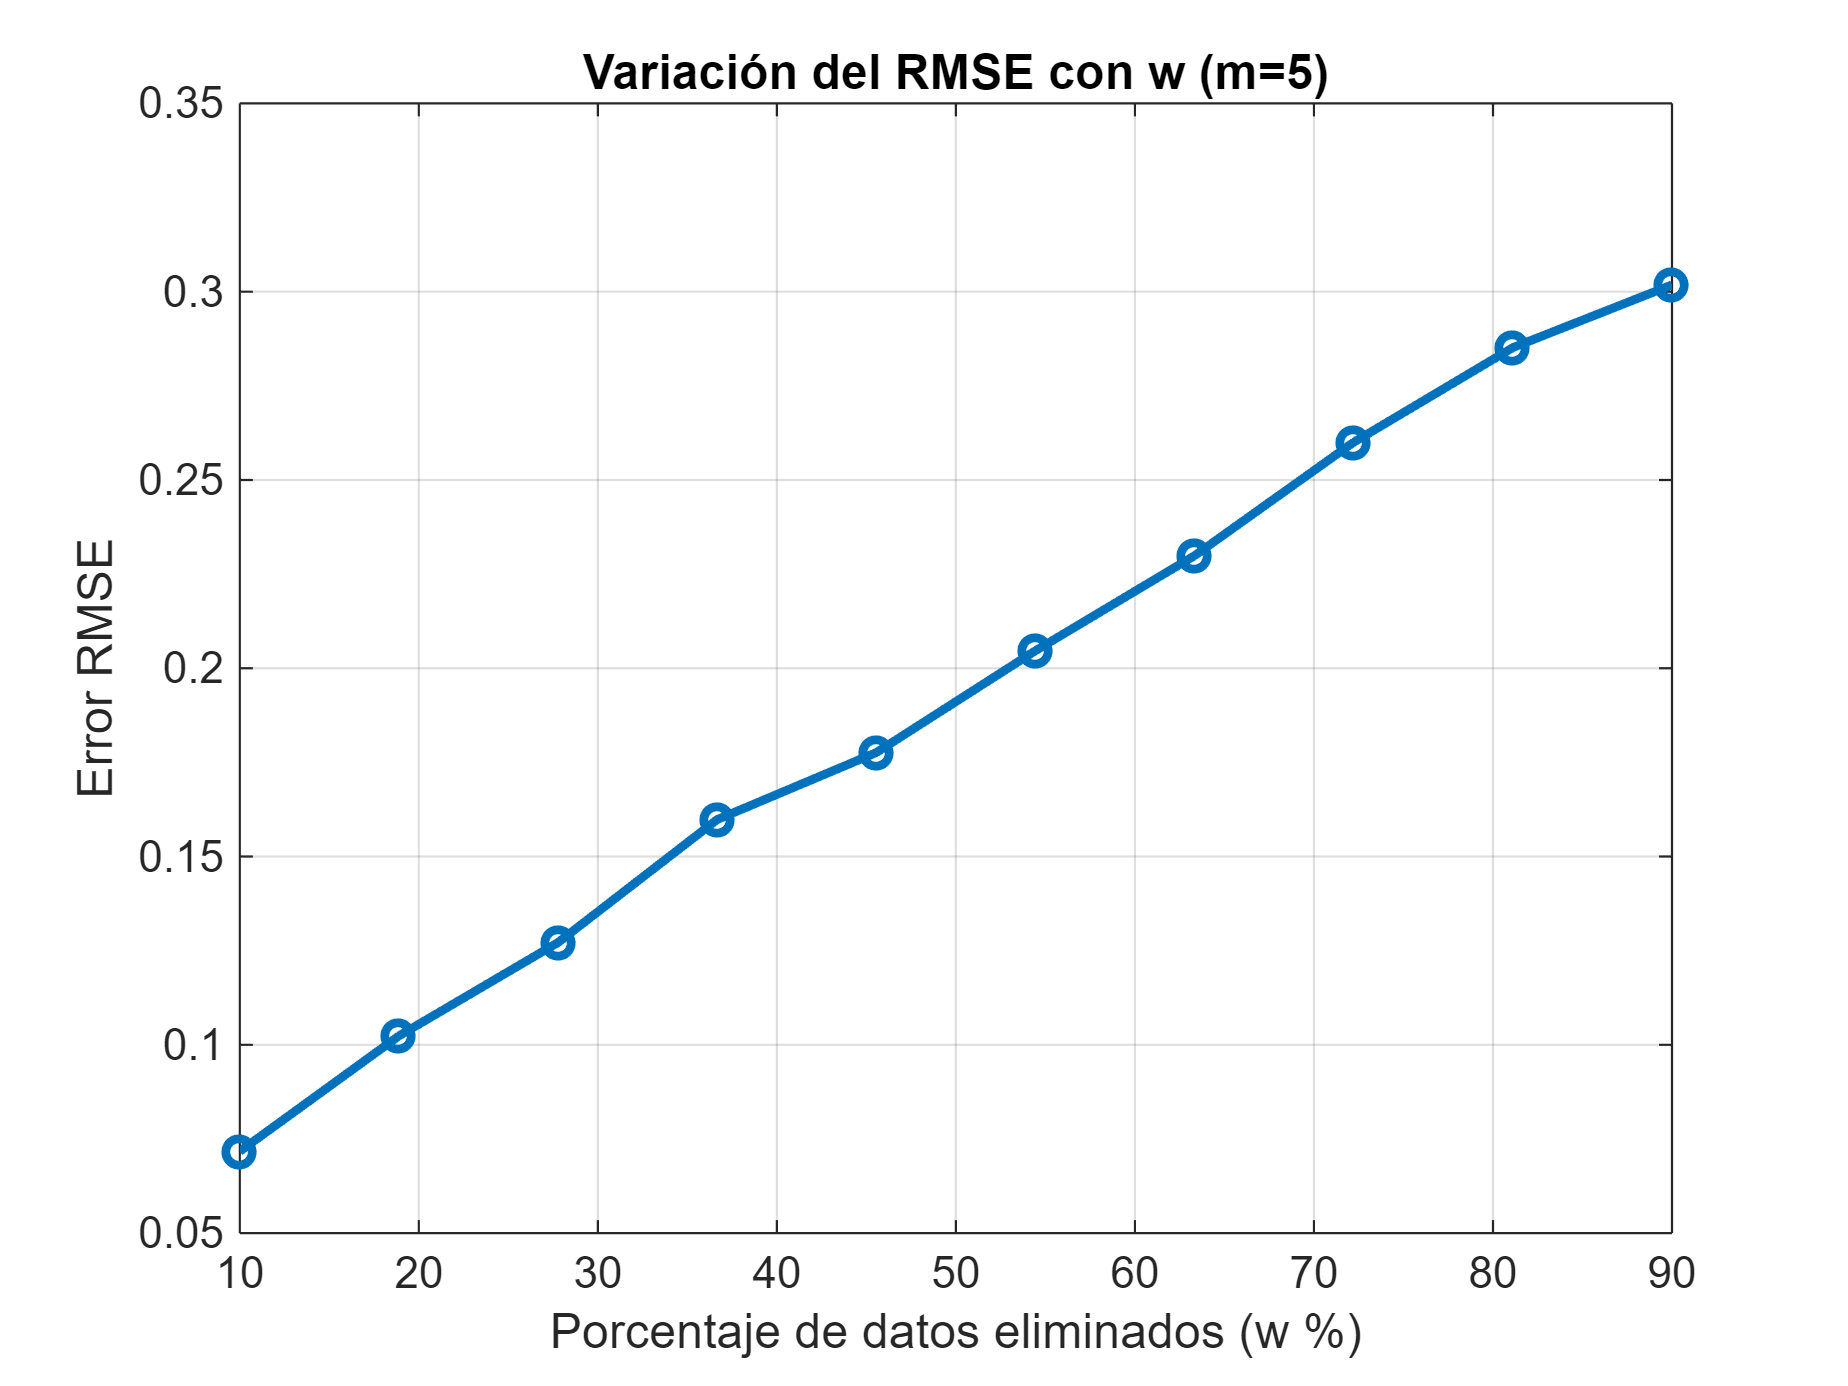


%Parámetros
N = 50; %Tamaño de la matriz
Delta_x = 1 / (N-1);
[x, y] = meshgrid( (0:N-1)* Delta_x, (0:N-1) * Delta_x);
z = 0; %Valores de z*
w_values = linspace(0.1, 0.9, 10); % Porcentajes de datos eliminados (10% a 90%)



%Función f. 0<= x,y,z<=1
f = @(x, y, z) x.^2 .*(sin(5*pi*y + 3*log(x.^3 + y.^2 + z +pi^2)) -1).^2 -...
    4*x.^2 .*y.^3.*(1-z)^(3/2) + (x + z - 1) .* (2*y - z) .* cos(30*(x + z))...
    .* log(6 + x.^2.*y.^2 + z.^3);




% Parámetros
N = 50; % Tamaño de la matriz
m = 5; % Número fijo de modos para SVD
max_iter = 1000;
tol = 1e-6;

% Vector para almacenar los errores RMSE
RMSE_values = zeros(size(w_values));

for k = 1:length(w_values)
    w = w_values(k);

    A1 = f(x, y, z);
    f_min1 = min(A1(:)); f_max1 = max(A1(:));
    A1 = 2 * (A1 - f_min1) / (f_max1 - f_min1) - 1;
    elems1 = rand(N, N) > w;
    A1_gappy = A1 .* elems1;

    % Aplicar SVD truncado a la matriz A1_gappy
    A_rec = truncated_svd(A1_gappy, m, max_iter, tol);

    % Calcular error RMSE comparando A1 (original) con A_rec (reconstruida)
    RMSE_values(k) = (1/N) * norm(A1 - A_rec, 'fro'); 
end

% Graficar RMSE vs. porcentaje de eliminación w
figure;
plot(w_values * 100, RMSE_values, 'o-', 'LineWidth', 2);
xlabel('Porcentaje de datos eliminados (w %)'); 
ylabel('Error RMSE'); 
title(sprintf('Variación del RMSE con w (m=%d)', m)); 
grid on;

Gráfica que representa los distintos errores cometidos en la reconstrucción de la matriz A1 variando el numero fijo de modos. 

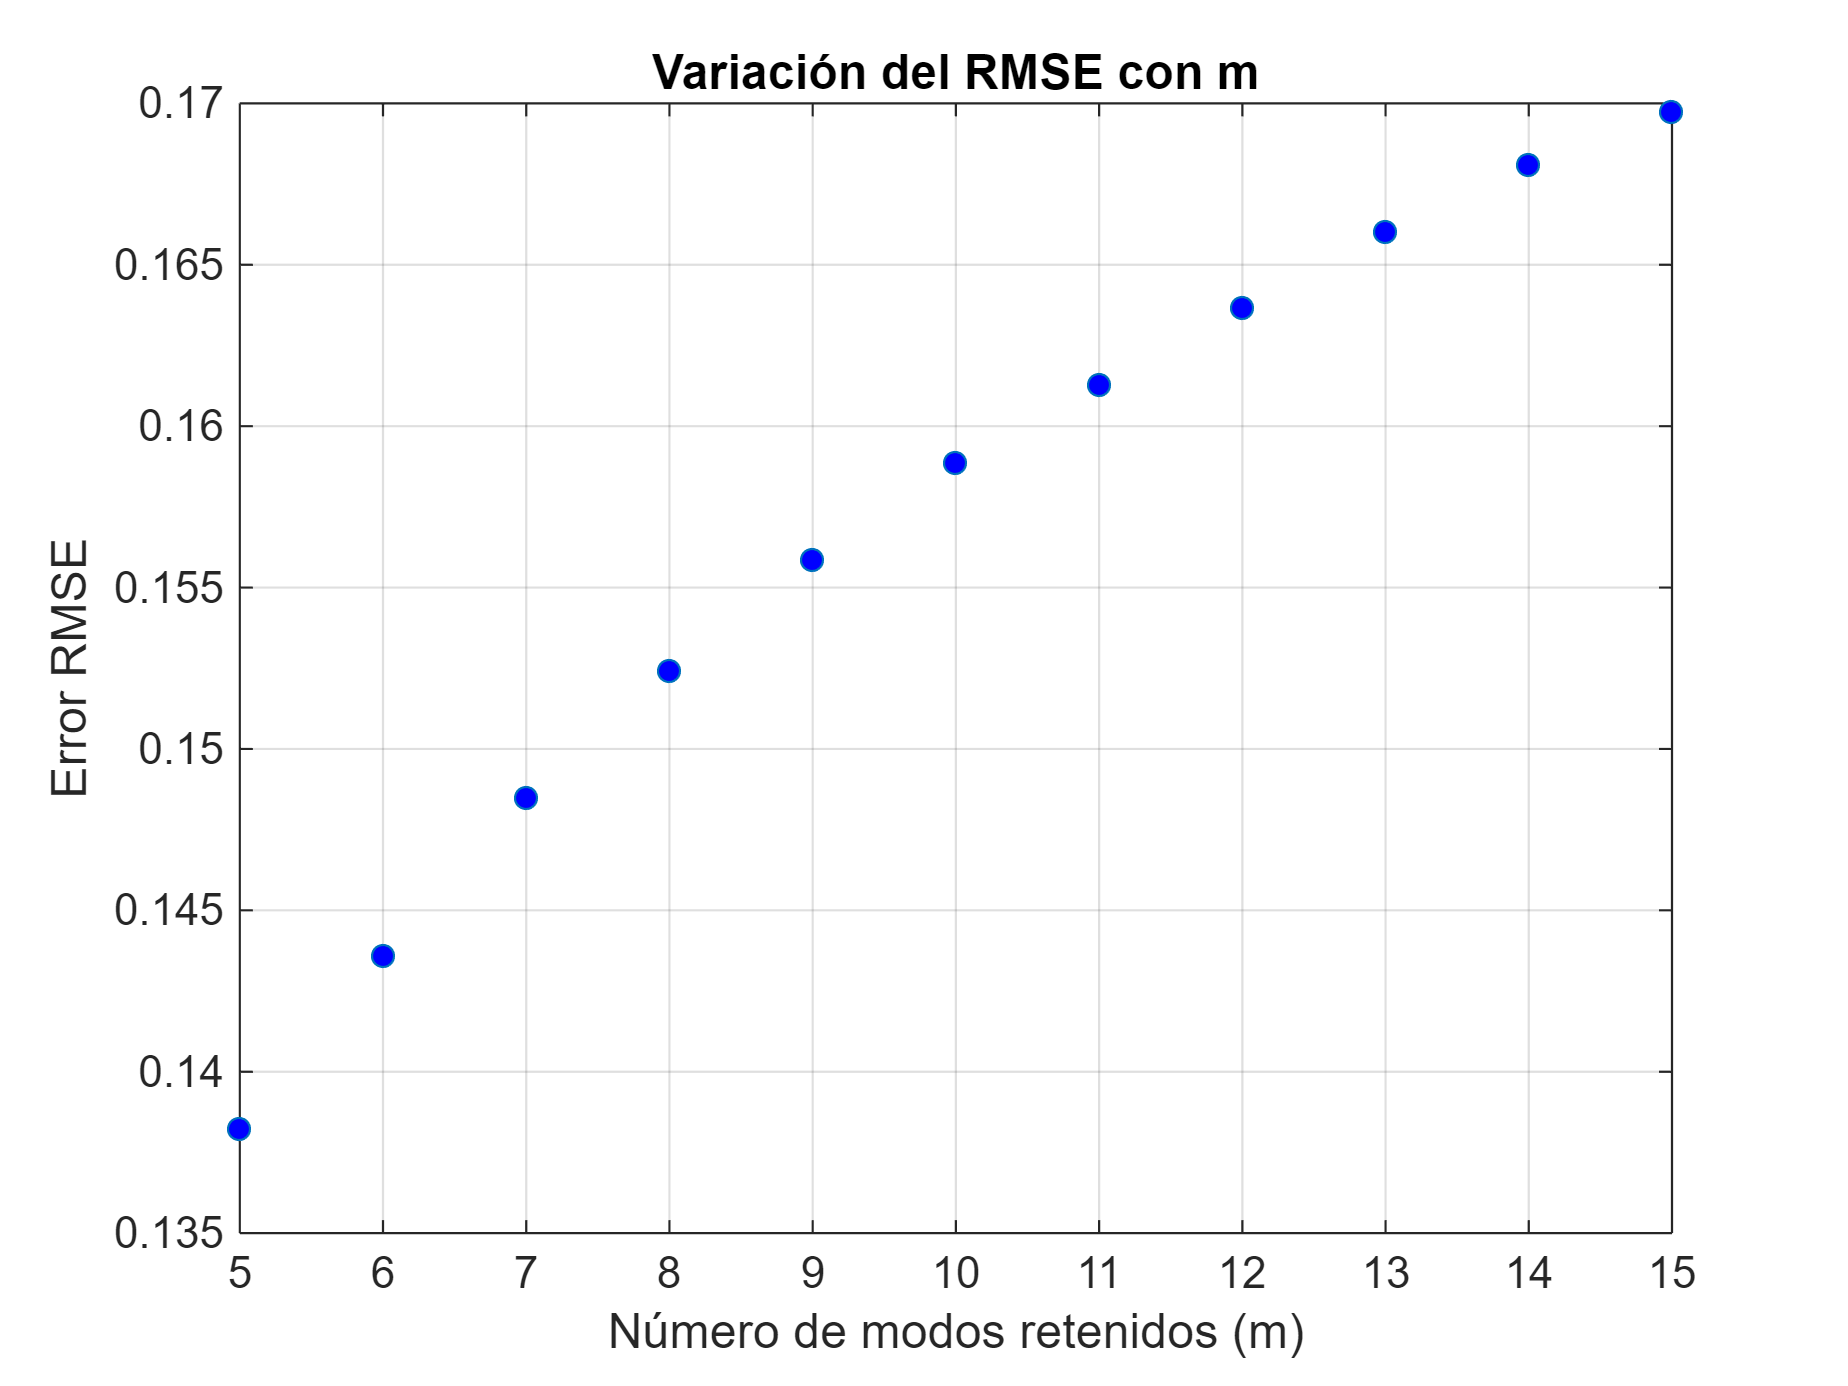


%Parámetros
N = 50; %Tamaño de la matriz
Delta_x = 1 / (N-1);
[x, y] = meshgrid( (0:N-1)* Delta_x, (0:N-1) * Delta_x);
z = 0; %Valores de z*
m_val = 5:15;
w = 0.3;


%Función f. 0<= x,y,z<=1
f = @(x, y, z) x.^2 .*(sin(5*pi*y + 3*log(x.^3 + y.^2 + z +pi^2)) -1).^2 -...
    4*x.^2 .*y.^3.*(1-z)^(3/2) + (x + z - 1) .* (2*y - z) .* cos(30*(x + z))...
    .* log(6 + x.^2.*y.^2 + z.^3);

A1 = f(x, y, z);
f_min1 = min(A1(:)); f_max1 = max(A1(:));
A1 = 2 * (A1 - f_min1) / (f_max1 - f_min1) - 1;
elems1 = rand(N, N) > w;
A1_gappy = A1 .* elems1;



% Parámetros
N = 50; % Tamaño de la matriz
max_iter = 1000;
tol = 1e-6;

% Vector para almacenar los errores RMSE
RMSE_values = zeros(size(m_val));

for k = 1:length(m_val)

    m = m_val(k);

   
    % Aplicar SVD truncado a la matriz A1_gappy
    A_rec = truncated_svd(A1_gappy, m, max_iter, tol);

    % Calcular error RMSE comparando A1 (original) con A_rec (reconstruida)
    RMSE_values(k) = (1/N) * norm(A1 - A_rec, 'fro'); 
end

% Graficar RMSE vs. numero de modos m
figure;
plot(m_val, RMSE_values, 'o', 'MarkerSize', 5, 'MarkerFaceColor', 'b'); % Solo puntos
xlabel('Número de modos retenidos (m)'); 
ylabel('Error RMSE'); 
xticks(5:1:15);
title('Variación del RMSE con m'); 
grid on;

Analizamos los resultados variando la reconstrucción inicial.

A_rec_media = truncated_svd(A1_gappy, m, max_iter, tol);
A_rec_aleatoria = truncated_svd2(A1_gappy, m, max_iter, tol);

RMSE_media = (1/N) *norm(A1- A_rec_media, 'fro');
disp(RMSE_media)

    0.1697



RMSE_aleatorio = (1/N) *norm(A1 - A_rec_aleatoria, 'fro');
disp(RMSE_aleatorio)

    0.1697



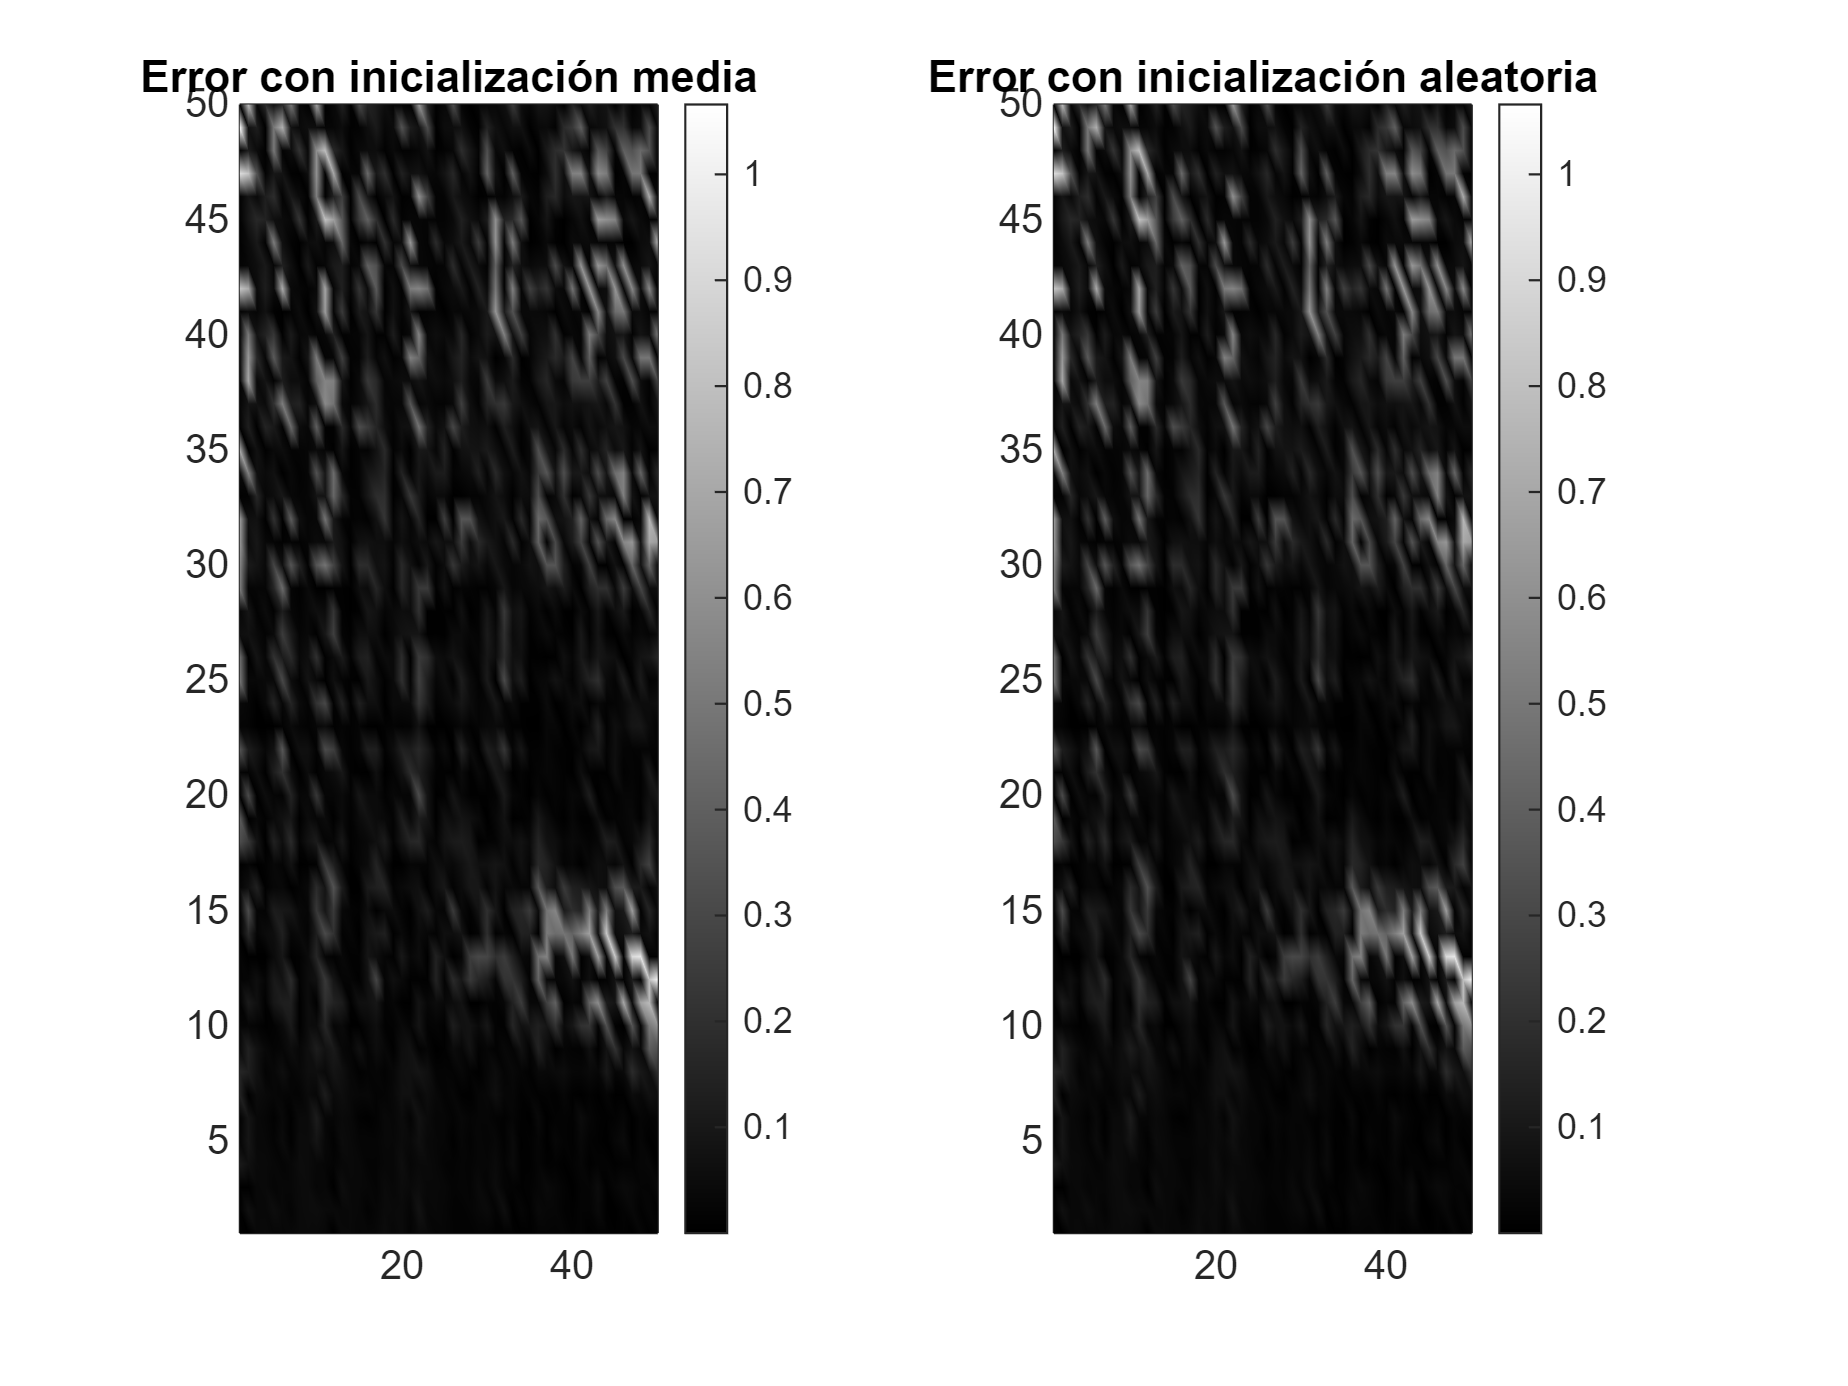


subplot(1,2,1); pcolor(abs(A1- A_rec_media)); shading interp; colormap('gray'); 
colorbar; title('Error con inicialización media'); 


subplot(1,2,2);
pcolor(abs(A1 - A_rec_aleatoria));  shading interp; colormap('gray'); 
colorbar; title('Error con inicialización aleatoria')